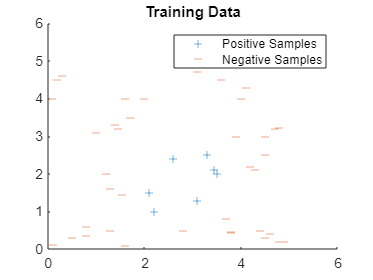

clear all
close all
%Training Data x y and x2 y2 for positive and negative points
x=[2.2,2.1,2.6,3.3,3.1,3.5,3.45];
y=[1,1.5,2.4,2.5,1.3,2,2.11];
x2=[0.11,0.5,0.8,0.8,1.3,1.6,2.8,1.7,2,1.6,3.7,3.8,3.8,4.5,4.4,4.8,4.9,4.6,4.3,4.2,3.9,4.5,4.5,4.7,4.8,3.1,3.6,4,4.1,0.1,0.2,0.3,1.55,1.3,1.22,1,1.4,1.45];    
y2=[0.11,0.3,0.35,0.6,0.5,0.1,0.5,3.5,4,4,0.8,0.45,0.46,0.3,0.5,0.2,0.2,0.4,2.1,2.2,3,2.5,3,3.2,3.23,4.7,4.5,4,4.3,4,4.5,4.6,1.44,1.6,2,3.1,3.3,3.2] ;
figure(1)
scatter(x,y,'+')
axis([0 6 0 6])
hold on
scatter(x2,y2,'_')
title('Training Data')
legend('Positive Samples','Negative Samples')

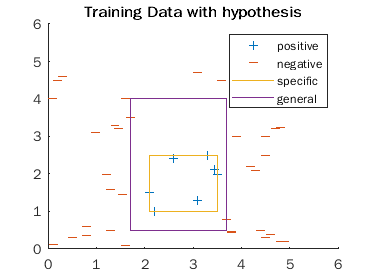


%hypothesis with specific and general
figure(2)
scatter(x,y,'+')
axis([0 6 0 6])
hold on
scatter(x2,y2,'_')
hold on


%Estimating Boundary of Specific Hypothesis
x3=[min(x),max(x),max(x),min(x),min(x)];
y3=[min(y),min(y),max(y),max(y),min(y)];
plot(x3,y3)
hold on
% 

%Estimating Boundary of general hypothesis
edgex=[2.8,1.7,2,3.7];
edgey=[0.5,3.5,4,0.8];
x4=[min(edgex),max(edgex),max(edgex),min(edgex),min(edgex)];
y4=[min(edgey),min(edgey),max(edgey),max(edgey),min(edgey)];
plot(x4,y4)
title('Training Data with hypothesis')
legend('positive','negative','specific','general')
hold off

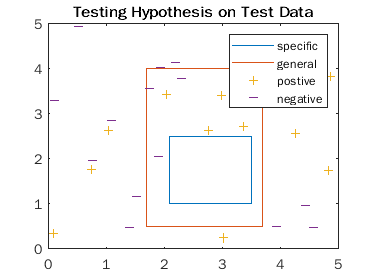


figure(3)
plot(x3,y3) %Specific  
axis([0 5 0 5])
hold on
plot(x4,y4) %General
hold on

%testing data
%generate 15 numbers from range (0 ,5)
rx=0+(5-0).*rand(15,1);
ry=0+(5-0).*rand(15,1);
rx2=0+(5-0).*rand(15,1);
ry2=0+(5-0).*rand(15,1);
scatter(rx,ry,'+')
hold on
scatter(rx2,ry2,'_')
title('Testing Hypothesis on Test Data')
legend('specific','general','postive','negative')


%Estimation on Trainning Samples
[in1,on1] = inpolygon(rx,ry,x3,y3); %Specific 
[in2,on2]=inpolygon(rx,ry,x4,y4);   %General
pts_specific_in=numel(rx(in1));
pts_specific_out=numel(rx(on1));
PTinspecificPositive=pts_specific_in+pts_specific_out;
points_in_generalPositive=numel(rx(in2));
points_out_generalPositive=numel(rx(on2));
PTingeneralPositive=points_in_generalPositive+points_out_generalPositive;

%calculation of accuracies on Trainning Samples
TotalpointsP=numel(rx);
PToutsideSPositive=TotalpointsP-PTinspecificPositive;
PToutsideGPositive=TotalpointsP-PTingeneralPositive;
inside_SpecficP=(PTinspecificPositive/TotalpointsP)*100;
outside_SpecificP=(PToutsideSPositive/TotalpointsP)*100;
inside_GeneralP=(PTingeneralPositive/TotalpointsP)*100;
outside_GeneralP=(PToutsideGPositive/TotalpointsP)*100;
PointTablePositive=table(PTinspecificPositive,PToutsideSPositive,PTingeneralPositive,PToutsideGPositive);
accuracytablePositive=table(inside_SpecficP,outside_SpecificP,inside_GeneralP,outside_GeneralP);

%Estimation on Testing Samples
[tin1,ton1] = inpolygon(rx2,ry2,x3,y3); %Specific 
[tin2,ton2]=inpolygon(rx2,ry2,x4,y4);   %General
tpts_specific_in=numel(rx(in1));
tpts_specific_out=numel(rx(on1));
tPTinspecificPositive=tpts_specific_in+tpts_specific_out;
tpoints_in_generalPositive=numel(rx(in2));
tpoints_out_generalPositive=numel(rx(on2));
tPTingeneralPositive=tpoints_in_generalPositive+tpoints_out_generalPositive;

%calculation of accuracies on Trainning Samples
tTotalpointsP=numel(rx2);
tPToutsideSPositive=tTotalpointsP-tPTinspecificPositive;
tPToutsideGPositive=tTotalpointsP-tPTingeneralPositive;
tinside_SpecficP=(tPTinspecificPositive/tTotalpointsP)*100;
toutside_SpecificP=(tPToutsideSPositive/tTotalpointsP)*100;
tinside_GeneralP=(tPTingeneralPositive/tTotalpointsP)*100;
toutside_GeneralP=(tPToutsideGPositive/tTotalpointsP)*100;
tPointTablePositive=table(tPTinspecificPositive,tPToutsideSPositive,tPTingeneralPositive,tPToutsideGPositive);
taccuracytablePositive=table(tinside_SpecficP,toutside_SpecificP,tinside_GeneralP,toutside_GeneralP);



%For Part 2 Circular Hypothesis
x=[2.2,2.1,2.6,3.3,3.1,3.5,3.45];
y=[1,1.5,2.4,2.5,1.3,2,2.11];
x2=[0.11,0.5,0.8,0.8,1.3,1.6,2.8,1.7,2,1.6,3.7,3.8,3.8,4.5,4.4,4.8,4.9,4.6,4.3,4.2,3.9,4.5,4.5,4.7,4.8,3.1,3.6,4,4.1,0.1,0.2,0.3,1.55,1.3,1.22,1,1.4,1.45];    
y2=[0.11,0.3,0.35,0.6,0.5,0.1,0.5,3.5,4,4,0.8,0.45,0.46,0.3,0.5,0.2,0.2,0.4,2.1,2.2,3,2.5,3,3.2,3.23,4.7,4.5,4,4.3,4,4.5,4.6,1.44,1.6,2,3.1,3.3,3.2] ;
figure(4)
scatter(x,y,'+')
axis([0 6 0 6])
hold on
scatter(x2,y2,'_')
title('Training Data')
legend('Positive Samples','Negative Samples')


%Using Recrangle Fucntion to Estimate Circle Boundary
hold on
pos = [min(x) min(y) 2 2];  %x y w h 
rectangle('Position',pos,'Curvature',[1 1])
axis equal

edgex=[2.8,1.7,2,3.7];
edgey=[0.5,3.5,4,0.8];
x4=[min(edgex),max(edgex),max(edgex),min(edgex),min(edgex)];
y4=[min(edgey),min(edgey),max(edgey),max(edgey),min(edgey)];
pos1=[min(x4) min(y4) 4 4];  %x y w h
rectangle('Position',pos1,'Curvature',[1 1])
title('Training Data with hypothesis')
legend('positive','negative','specific','general')

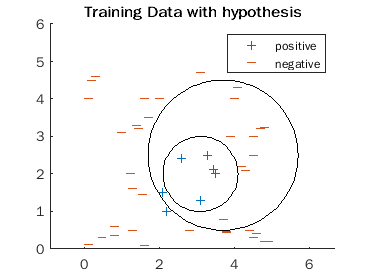

hold off


figure(5)
rx=0+(5-0).*rand(15,1);
ry=0+(5-0).*rand(15,1);
rx2=0+(5-0).*rand(15,1);
ry2=0+(5-0).*rand(15,1);
scatter(rx,ry,'+')
hold on
scatter(rx2,ry2,'_')
title('Testing Hypothesis on Test Data')
legend('specific','general','postive','negative')


hold on
pos = [min(x) min(y) 2 2];  %x y w h 
rectangle('Position',pos,'Curvature',[1 1])
axis equal

edgex=[2.8,1.7,2,3.7];
edgey=[0.5,3.5,4,0.8];
x4=[min(edgex),max(edgex),max(edgex),min(edgex),min(edgex)];
y4=[min(edgey),min(edgey),max(edgey),max(edgey),min(edgey)];
pos1=[min(x4) min(y4) 4 4];  %x y w h
rectangle('Position',pos1,'Curvature',[1 1])
title('Testing Data with hypothesis')
legend('positive','negative','specific','general')

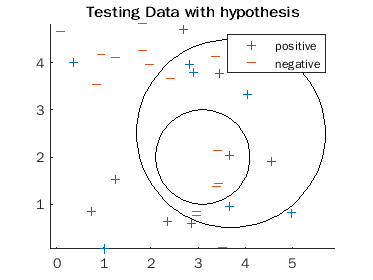

hold off


%Estimation on Trainning Samples
[in1,on1] = inpolygon(rx,ry,x3,y3); %Specific 
[in2,on2]=inpolygon(rx,ry,x4,y4);   %General
pts_specific_in=numel(rx(in1));
pts_specific_out=numel(rx(on1));
PTinspecificPositive=pts_specific_in+pts_specific_out;
points_in_generalPositive=numel(rx(in2));
points_out_generalPositive=numel(rx(on2));
PTingeneralPositive=points_in_generalPositive+points_out_generalPositive;

%calculation of accuracies on Trainning Samples
TotalpointsP=numel(rx);
PToutsideSPositive=TotalpointsP-PTinspecificPositive;
PToutsideGPositive=TotalpointsP-PTingeneralPositive;
inside_SpecficP=(PTinspecificPositive/TotalpointsP)*100;
outside_SpecificP=(PToutsideSPositive/TotalpointsP)*100;
inside_GeneralP=(PTingeneralPositive/TotalpointsP)*100;
outside_GeneralP=(PToutsideGPositive/TotalpointsP)*100;
PointTablePositive=table(PTinspecificPositive,PToutsideSPositive,PTingeneralPositive,PToutsideGPositive);
accuracytablePositive=table(inside_SpecficP,outside_SpecificP,inside_GeneralP,outside_GeneralP);

%Estimation on Testing Samples
[tin1,ton1] = inpolygon(rx2,ry2,x3,y3); %Specific 
[tin2,ton2]=inpolygon(rx2,ry2,x4,y4);   %General
tpts_specific_in=numel(rx(in1));
tpts_specific_out=numel(rx(on1));
tPTinspecificPositive=tpts_specific_in+tpts_specific_out;
tpoints_in_generalPositive=numel(rx(in2));
tpoints_out_generalPositive=numel(rx(on2));
tPTingeneralPositive=tpoints_in_generalPositive+tpoints_out_generalPositive;

%calculation of accuracies on Trainning Samples
tTotalpointsP=numel(rx2);
tPToutsideSPositive=tTotalpointsP-tPTinspecificPositive;
tPToutsideGPositive=tTotalpointsP-tPTingeneralPositive;
tinside_SpecficP=(tPTinspecificPositive/tTotalpointsP)*100;
toutside_SpecificP=(tPToutsideSPositive/tTotalpointsP)*100;
tinside_GeneralP=(tPTingeneralPositive/tTotalpointsP)*100;
toutside_GeneralP=(tPToutsideGPositive/tTotalpointsP)*100;
tPointTablePositive=table(tPTinspecificPositive,tPToutsideSPositive,tPTingeneralPositive,tPToutsideGPositive);
taccuracytablePositive=table(tinside_SpecficP,toutside_SpecificP,tinside_GeneralP,toutside_GeneralP);


